# Part1 Cross-USRP Wi-Fi Based OFDM transmission

## Resolve Cross-Device Synchronization Issues

%Part1(1):
clear all; clc;
function [radio_Tx,radio_Rx] = USRP_init(rx_length)

platform = "N200/N210/USRP2";
address  = '192.168.10.2';
USRPGain            = 5;  
USRPCenterFrequency = 885*1e6;  

radio_Tx = comm.SDRuTransmitter(...
    'Platform',             platform, ... 
    'IPAddress',            address, ...
    'CenterFrequency',      USRPCenterFrequency, ...
    'Gain',                 USRPGain, ...
    'InterpolationFactor',  100);

radio_Rx = comm.SDRuReceiver(...
    'Platform',             "B210", ...
    'SerialNum',            "315EEDF", ...
    'CenterFrequency',      USRPCenterFrequency, ...
    'Gain',                 20, ...
    'SamplesPerFrame',      rx_length, ...
    'MasterClockRate',      20e6, ...
    'DecimationFactor',     20, ...
    'OutputDataType',       'double') ; 

end

Computer: IP address = 192.168.10.1, subnet mask = [255.255.255.0](https://l.messenger.com/l.php?u=http%3A%2F%2F255.255.255.0%2F&h=AT2yiKKdXi0BZPIeGuamJ_agMbXRSnVfi_JpTlAdBPy7KCjpJpd-D0JTUKYv1wdTpikL5pNG3Ed6V5af95Ubs8crAzu_Dzs8H1r2SzrDUOC0mZRWk6U1Qwlo_jopiiXzUdZbPg)

USRP 2920:  IP address = [192.168.10.2](http://192.168.10.2/) 

USRP 2901: IP address = "

Download the UHD driver and connect USRP 2901 with PC (without power).  Renew the driver. Last, we can check if we find two USRP successfully by "findsdru()" in command line of matlab.

%Part1(2)

At first, we prepend and append zero samples to the transmit frame, so that the start and end of the frame are clearly visible in the received time-domain signal. For the receiver side, we capture a time window longer than the expected frame length, which avoid the effect of timing offset between two USRPs.

To ensure complete frame capture at USRP 2, each frame is transmitted multiple times and the receiver stores all captured signals. A power threshold is used to ignore the initial noisy buffers caused by USRP latency. For each valid buffer, we locate the LTS peak to determine the frame start and verify that the entire data section fits within the received samples. If a buffer is incomplete, we simply check the next one. This guarantees that at least one full, uncut frame is correctly captured.

% Part1(3)
clear all; clc;

%parameters:
Nfft = 64;
N_CP = 16;
Fs = 1e6;
M = 4;
numDataSym = 100;
N_frames = 10; %收10段資料
threshold = 1e-6; %power threshold
N_trans = 100; %transmit 2000 times

all_sc = [-26:-1 0 1:26]; %52 tones in total
pilots_sc = [-21 -7 7 21]; %4 pilot tones
data_sc = setdiff(all_sc, pilots_sc);      % 48 data tones
data_sc(data_sc == 0) = [];
toIdx = @(k)  mod(k, Nfft)+1;

%Generate 100 OFDM symbol
%Zero padding
Pre_pad = zeros(1,100);
Post_pad = zeros(1,100);

% STS
S_used = sqrt(13/6) * [0, 0, 1+1j, 0, 0, 0, -1-1j, 0, 0, 0, 1+1j, 0, 0, 0, -1-1j, 0, 0, 0, -1-1j, 0, 0, 0, 1+1j, ...
        0, 0, 0, 0, 0 ,0, 0, -1-1j, 0, 0, 0, -1-1j, 0, 0, 0, 1+1j, 0, 0, 0, 1+1j, 0, 0, 0, 1+1j, 0, 0, 0, 1+1j, 0, 0];
X_STS = zeros(1, Nfft);
X_STS(toIdx(all_sc)) = S_used;   
x_sts64  = ifft(X_STS, Nfft);      
x_sts16 = x_sts64(1:16);         
x_sts160 = repmat(x_sts16, 1, 10);

% LTS
L_used = [1,1,-1,-1,1,1,-1,1,-1,1,1,1,1,1,1,-1,-1,1,1,-1,1,-1,1,1,1,1,0,1,...
            -1,-1,1,1,-1,1,-1,1,-1,-1,-1,-1,-1,1,1,-1,-1,1,-1,1,-1,1,1,1,1] ;   
X_LTS = zeros(1, Nfft);
X_LTS(toIdx(all_sc)) = L_used;
x_lts      = ifft(X_LTS, Nfft);
x_lts160 = [x_lts(end-2*N_CP+1:end), x_lts, x_lts]; 

frame_data = [];
txBits = cell(1, numDataSym); 
pilotSym  = cell(1, numDataSym);                  

% 100 OFDM symbol
for nSym = 1:numDataSym
    X_ofdm = zeros(1, Nfft);
    % pilot: random BPSK
    pilot_bits = randi([0 1], 1, 4);
    pilot_sym  = 1 - 2*pilot_bits;
    X_ofdm(toIdx(pilots_sc)) = pilot_sym; 
    pilotSym{nSym}    = pilot_sym(:); 

    % data: 4-QAM 
    data_bits = randi([0 1], 48*log2(M), 1);
    txBits{nSym} = data_bits;
    data_sym  = qammod(data_bits, M, 'InputType','bit', 'UnitAveragePower', true);
    X_ofdm(toIdx(data_sc)) = data_sym.'; 

    x_ofdm = ifft(X_ofdm, Nfft);
    x_cp_ofdm   = [x_ofdm(end-N_CP+1:end), x_ofdm];
    frame_data = [frame_data, x_cp_ofdm]; 
 
end
% combine: 
tx_frame = [Pre_pad, x_sts160, x_lts160, frame_data, Post_pad];

% plot:
t_frame_us = (0:numel(tx_frame)-1)/Fs*1e6;
i1 = numel(Pre_pad) + numel(x_sts160);
i2 = i1 + numel(x_lts160);
i3 = i2 + numel(frame_data);

rx_length = 3*length(tx_frame) ;
rx_buffer = zeros(N_frames, rx_length);
rx_buffer_all = [];
[radio_Tx, radio_Rx] = USRP_init(rx_length);

count = 0;
for k = 1:N_trans %N_trans = 2000
    tunderrun = radio_Tx(tx_frame(:));       % send k-th signal
    [rx_frame, ~, toverflow] = step(radio_Rx); % receive signal
    Power = mean(abs(rx_frame).^2);
    if Power > threshold && ~toverflow 
        count = count + 1;
        rx_buffer(count,:) = rx_frame(:).';
        rx_buffer_all = [rx_buffer_all, rx_frame.'];
    end
    if count == N_frames
        break;
    end
end
release(radio_Tx);
release(radio_Rx);

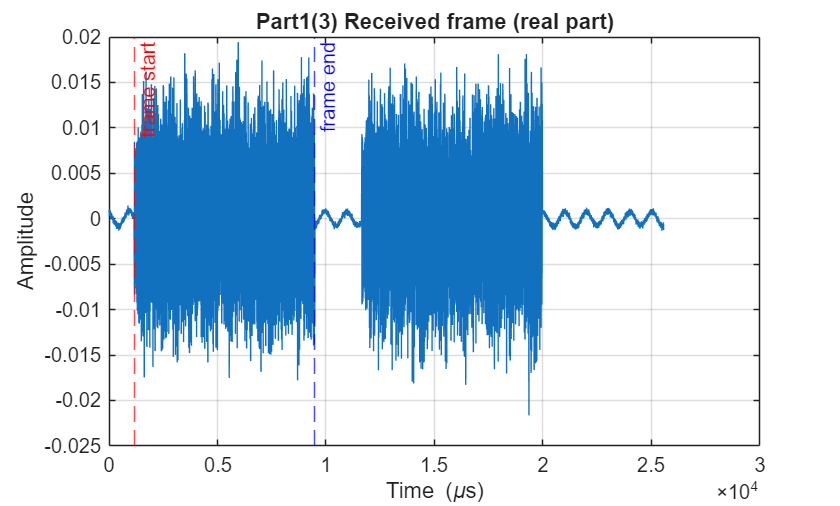

for i = 2:N_frames
    f = rx_buffer(i,:);
    lts_noCP = [x_lts, x_lts].';        % length 128
    h_mf = conj(flipud(lts_noCP));      % match filter
    mf   = conv(f(:), h_mf, 'full');    % convolution
    a    = abs(mf);
    [pks, locs] = findpeaks(a, 'MinPeakDistance', 64);
    mx = max(pks);
    keep = pks >= 0.9*mx;                             
    locs = locs(keep);
    pk = locs(1); 

    data_end = pk-1 + 100*(Nfft+N_CP);
    start_LTS_noCP = pk - (numel(lts_noCP) - 1);
    LEN_LTS_noCP   = numel(lts_noCP);                          % 128
    LEN_STS        = numel(x_sts160);                          % 160
    start_STS      = start_LTS_noCP - (LEN_STS + 2*N_CP);
    start_DATA     = start_LTS_noCP + LEN_LTS_noCP;

    if  data_end < rx_length && start_STS > 0
        break;
    end
end  


%% --- Plot ---
figure; 
% subplot(2,1,1);
t_sig   = (0:length(f)-1)/Fs*1e6;
plot(t_sig, real(f), 'LineWidth', 1.0); grid on;
xlabel('Time (\mus)'); ylabel('Amplitude');
title('Part1(3) Received frame (real part)');
xline((start_STS)/Fs*1e6,'--r','frame start');
% xline(start_LTS_noCP/Fs*1e6,'--k','LTS no-CP start');
xline((start_DATA+numel(frame_data))/Fs*1e6,'--b','frame end');

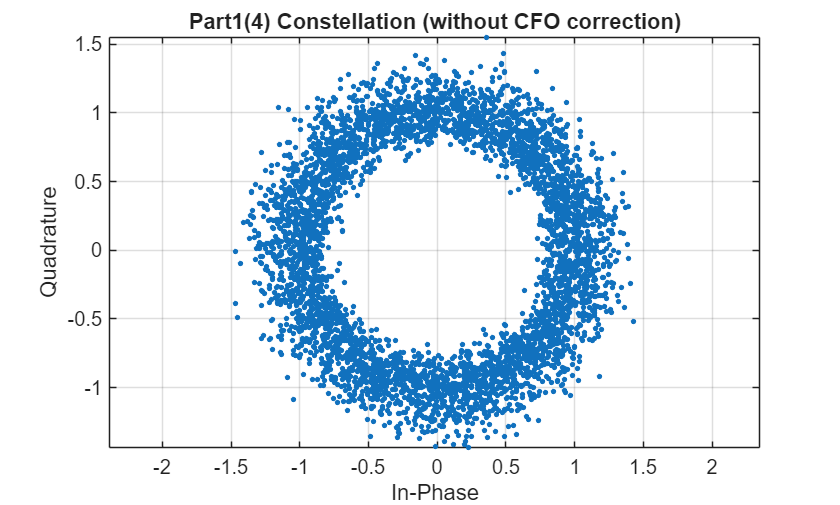

% Part1(4)
L = 64;
rx_lts_1 = f(start_LTS_noCP + (0:L-1));
Rx_LTS_1 = fft(rx_lts_1, Nfft);
H_LTS1 = Rx_LTS_1 .* X_LTS;

rx_lts_2 = f(start_LTS_noCP + L + (0:L-1));
Rx_LTS_2 = fft(rx_lts_2, Nfft);
H_LTS2   = Rx_LTS_2 .* X_LTS;

H_est = 0.5 * (H_LTS1 + H_LTS2);          
H_est_data = H_est(toIdx(data_sc)).';

Xhat_all = [];
for nSym = 1:numDataSym % for 100 ofdm symbol
    s0   = start_DATA + (nSym-1)*(Nfft+N_CP);
    y_td = f(s0 + N_CP + (0:Nfft-1));%remove cp
    Y_fd = fft(y_td, Nfft);%fft
    %equalization
    Yd_fd = Y_fd(toIdx(data_sc)).';
    Ye_fd = Yd_fd ./ H_est_data;
    Xhat_all = [Xhat_all, Ye_fd'];
end

% plot the constellation
figure; 
plot(real(Xhat_all), imag(Xhat_all), '.', 'MarkerSize', 8); grid on; axis equal;
xlabel('In-Phase'); ylabel('Quadrature');
title('Part1(4) Constellation (without CFO correction)');

Yes, we observe that the constellation is rotating.

% Part1(5)
%LTS based estimation
L = 64;
LTS1 = f(start_LTS_noCP + (0:L-1));
LTS2 = f(start_LTS_noCP + L + (0:L-1));

num = sum(LTS2 .* conj(LTS1));       
phi = angle(num);
cfo_hat_Hz = phi * Fs / (2*pi*L);

fprintf('Estimated CFO = %.2f Hz\n', cfo_hat_Hz);

Estimated CFO = -982.62 Hz


Our CFO correction is based on two consecutive LTS.

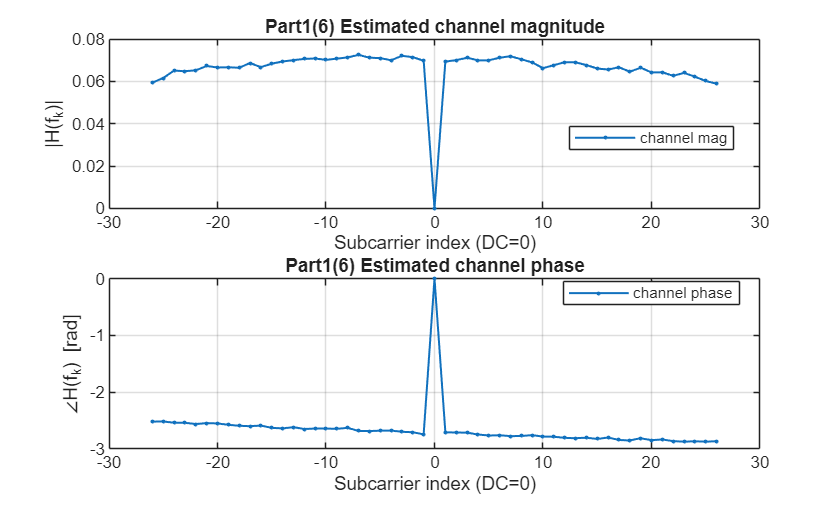

% Part1(6)
%CFO correction
n     = (0:length(f)-1).';
f_cfo = (f(:) .* exp(-1j*2*pi*cfo_hat_Hz*n/Fs)).';
% take lts
y_lts1 = f_cfo(start_LTS_noCP + (0:Nfft-1));
y_lts2 = f_cfo(start_LTS_noCP + Nfft + (0:Nfft-1));
%fft
Y_lts1 = fft(y_lts1, Nfft);
Y_lts2 = fft(y_lts2, Nfft);
%channel estimation
H_est_1 = zeros(1, Nfft);
H_est_2 = zeros(1, Nfft);
H_est_1(toIdx(all_sc)) = Y_lts1(toIdx(all_sc)) .* X_LTS(toIdx(all_sc));
H_est_2(toIdx(all_sc)) = Y_lts2(toIdx(all_sc)) .* X_LTS(toIdx(all_sc));
H_est = 0.5*(H_est_1 + H_est_2);

% magnitude
figure; 
subplot(2,1,1);
plot(all_sc, abs(H_est(toIdx(all_sc))), '.-', 'LineWidth', 1);
grid on; 
xlabel('Subcarrier index (DC=0)'); ylabel('|H(f_k)|');
title('Part1(6) Estimated channel magnitude');
legend('channel mag','Location','best');
% phase
subplot(2,1,2);
plot(all_sc, unwrap(angle(H_est(toIdx(all_sc)))), '.-', 'LineWidth', 1);
grid on; 
xlabel('Subcarrier index (DC=0)'); ylabel('∠H(f_k) [rad]');
title('Part1(6) Estimated channel phase');
legend('channel phase','Location','best');

After CFO correction, the channel magnitude becomes smooth and stable, while the channel phase shows a nearly linear trend, which implies that our CFO correction is good.

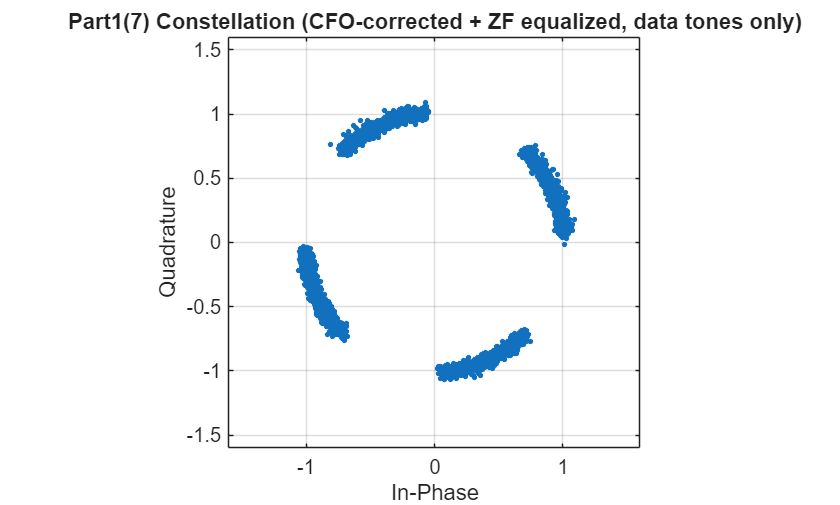

%Part1(7):
X_EQ_noCPE = zeros(numDataSym, Nfft);
for nSym = 1:numDataSym % for 100 ofdm symbol
    s0   = start_DATA + (nSym-1)*(Nfft+N_CP);
    y_td = f_cfo(s0 + N_CP + (0:Nfft-1));%remove cp
    Y_fd = fft(y_td, Nfft);%fft

    % equalization
    X_eq = zeros(1, Nfft);
    X_eq(toIdx(all_sc)) = Y_fd(toIdx(all_sc)) ./ (H_est(toIdx(all_sc)) + 1e-12);
    % parallel to serial convertor
    X_EQ_noCPE(nSym, :) = X_eq;
end
Xeq_all = X_EQ_noCPE(:, toIdx(data_sc));
% plot the constellation(CFO-corrected)
figure;
plot(real(Xeq_all(:)), imag(Xeq_all(:)), '.', 'MarkerSize', 8); grid on; axis equal;
xlabel('In-Phase'); ylabel('Quadrature');
title('Part1(7) Constellation (CFO-corrected + ZF equalized, data tones only)');
xlim([-1.6 1.6]); ylim([-1.6 1.6]);

The figure after CFO correction is much concentrate compared to the figure before CFO correction. However, we can still see some rotation in this figure.

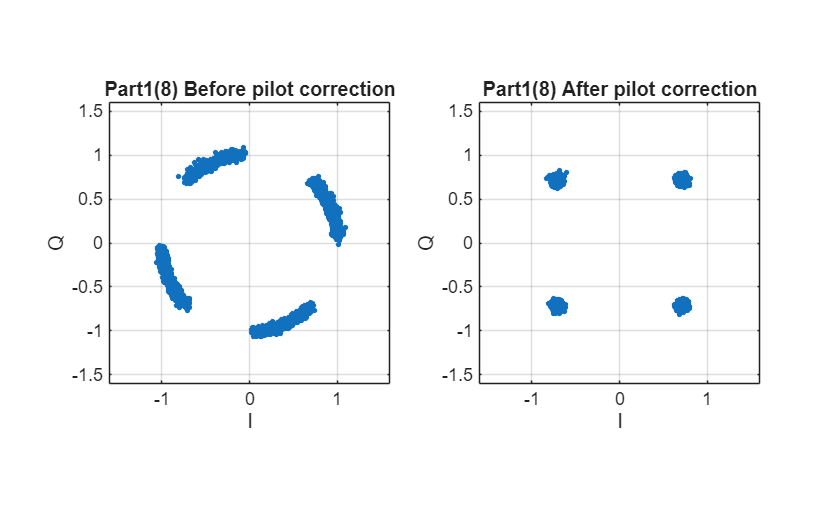

%Part1(8):
LEN_SYM_CP = Nfft + N_CP;
Y_EQ_noCPE = zeros(numDataSym, Nfft);
Y_EQ_CPEcorr = zeros(numDataSym, Nfft);
phi_pilot = zeros(1, numDataSym);

for m = 1:numDataSym
    s0 = start_DATA + (m-1)*LEN_SYM_CP;
    y_td = f_cfo(s0 + N_CP + (0:Nfft-1));
    Y_fd = fft(y_td, Nfft);
    Y_eq = zeros(1, Nfft);
    Y_eq(toIdx(all_sc)) = Y_fd(toIdx(all_sc)) ./ (H_est(toIdx(all_sc)) + 1e-12);
    Y_EQ_noCPE(m, :) = Y_eq;
    
    % posistion of 4 pilot, estimate residual phase error
    Rp = Y_eq(toIdx(pilots_sc));        % pilot after equalization
    Pk = pilotSym{m}(:).';              % known pilot from transmitter
    phi = angle(sum(Rp .* conj(Pk)));   % phase difference
    phi_pilot(m) = phi;
    
    % remove CPE
    Y_EQ_CPEcorr(m, :) = Y_eq * exp(-1j * phi);
end

% take the data part out
X_data_noCPE = Y_EQ_noCPE(:, toIdx(data_sc));
X_data_CPEcorr = Y_EQ_CPEcorr(:, toIdx(data_sc));

%plot the constellation
figure;
subplot(1,2,1);
plot(real(X_data_noCPE(:)), imag(X_data_noCPE(:)), '.', 'MarkerSize', 8);
title('Part1(8) Before pilot correction');
xlabel('I'); ylabel('Q'); grid on; axis equal;
xlim([-1.6 1.6]); ylim([-1.6 1.6]);

subplot(1,2,2);
plot(real(X_data_CPEcorr(:)), imag(X_data_CPEcorr(:)), '.', 'MarkerSize', 8);
title('Part1(8) After pilot correction');
xlabel('I'); ylabel('Q'); grid on; axis equal;
xlim([-1.6 1.6]); ylim([-1.6 1.6]);

We find that the pilot tone correction successfully eliminate the rotation, and thus we get low BER( = 0) in (9).

%9:
bitsPerSym = 48 * log2(M);

rxBits_all = zeros(numDataSym * 48 * log2(M), 1);
txBits_all = zeros(numDataSym * 48 * log2(M), 1);

wptr = 0;
for m = 1:numDataSym
    Xd = Y_EQ_CPEcorr(m, toIdx(data_sc));          % 1×48 complex
    rxBits_m = qamdemod(Xd.', M, 'OutputType','bit', 'UnitAveragePower', true);
    txBits_m = txBits{m}(:);
    rxBits_all(wptr + (1:bitsPerSym)) = rxBits_m;
    txBits_all(wptr + (1:bitsPerSym)) = txBits_m;
    wptr = wptr + bitsPerSym;
end
%BER
[numErr, BER] = biterr(txBits_all, rxBits_all);
fprintf('Part1(9)BER for this single frame: %d / %d  = %.3e\n', numErr, numel(txBits_all), BER);

Part1(9)BER for this single frame: 0 / 9600  = 0.000e+00


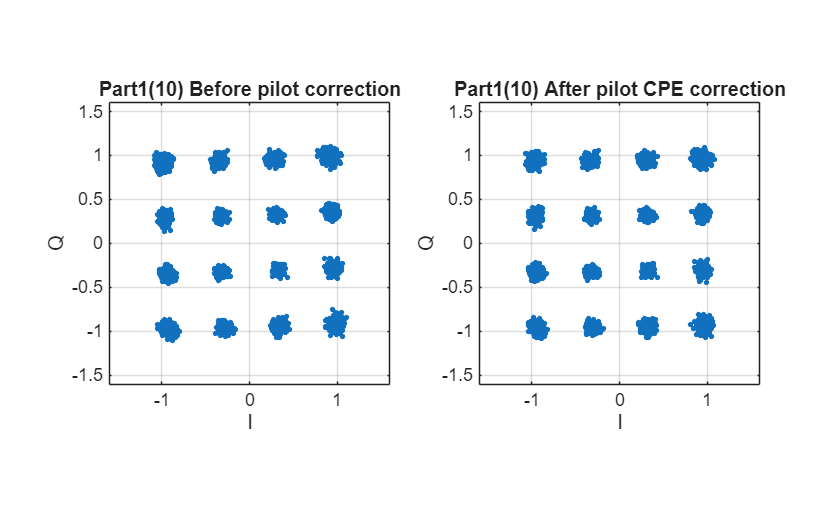

%Part1(10)
clear all; clc;

%parameters:
Nfft = 64;
N_CP = 16;
Fs = 1e6;
M = 16;
numDataSym = 100;
N_frames = 10; %收10段資料
threshold = 1e-6; %power threshold
N_trans = 100; %transmit 2000 times

all_sc = [-26:-1 0 1:26]; %52 tones in total
pilots_sc = [-21 -7 7 21]; %4 pilot tones
data_sc = setdiff(all_sc, pilots_sc);  
data_sc(data_sc == 0) = [];% 48 data tones
toIdx = @(k)  mod(k, Nfft)+1;

%Generate 100 OFDM symbol
%Zero padding
Pre_pad = zeros(1,100);
Post_pad = zeros(1,100);

% STS
S_used = sqrt(13/6) * [0, 0, 1+1j, 0, 0, 0, -1-1j, 0, 0, 0, 1+1j, 0, 0, 0, -1-1j, 0, 0, 0, -1-1j, 0, 0, 0, 1+1j, ...
        0, 0, 0, 0, 0 ,0, 0, -1-1j, 0, 0, 0, -1-1j, 0, 0, 0, 1+1j, 0, 0, 0, 1+1j, 0, 0, 0, 1+1j, 0, 0, 0, 1+1j, 0, 0];
X_STS = zeros(1, Nfft);
X_STS(toIdx(all_sc)) = S_used;   
x_sts64  = ifft(X_STS, Nfft);      
x_sts16 = x_sts64(1:16);         
x_sts160 = repmat(x_sts16, 1, 10);

% LTS
L_used = [1,1,-1,-1,1,1,-1,1,-1,1,1,1,1,1,1,-1,-1,1,1,-1,1,-1,1,1,1,1,0,1,...
            -1,-1,1,1,-1,1,-1,1,-1,-1,-1,-1,-1,1,1,-1,-1,1,-1,1,-1,1,1,1,1] ;   
X_LTS = zeros(1, Nfft);
X_LTS(toIdx(all_sc)) = L_used;
x_lts      = ifft(X_LTS, Nfft);
x_lts160 = [x_lts(end-2*N_CP+1:end), x_lts, x_lts]; 

frame_data = [];
pilotSym  = cell(1, numDataSym);
% 100 OFDM symbol
for nSym = 1:numDataSym
    X_ofdm = zeros(1, Nfft);
    % pilot: random BPSK
    pilot_bits = randi([0 1], 1, 4);
    pilot_sym  = 1 - 2*pilot_bits;
    X_ofdm(toIdx(pilots_sc)) = pilot_sym; %放在toIdx(pilots_sc)
    pilotSym{nSym}    = pilot_sym(:); 

    % data: 4-QAM 
    data_bits = randi([0 1], 48*log2(M), 1);
    txBits{nSym} = data_bits;
    data_sym  = qammod(data_bits, M, 'InputType','bit', 'UnitAveragePower', true);
    X_ofdm(toIdx(data_sc)) = data_sym.'; %放在toIdx(data_sc)
    %txSymTone{nSym} = data_sym(:);        
    %txSymAll = [txSymAll; data_sym(:)];   

    x_ofdm = ifft(X_ofdm, Nfft);
    x_cp_ofdm   = [x_ofdm(end-N_CP+1:end), x_ofdm];
    frame_data = [frame_data, x_cp_ofdm]; 
 
end
%combine: 
tx_frame = [Pre_pad, x_sts160, x_lts160, frame_data, Post_pad];

%plot:
t_frame_us = (0:numel(tx_frame)-1)/Fs*1e6;
i1 = numel(Pre_pad) + numel(x_sts160);
i2 = i1 + numel(x_lts160);
i3 = i2 + numel(frame_data);

rx_length = 3*length(tx_frame) ;
rx_buffer = zeros(N_frames, rx_length);
rx_buffer_all = [];
[radio_Tx, radio_Rx] = USRP_init(rx_length);

count = 0;
for k = 1:N_trans %N_trans = 2000
    tunderrun = radio_Tx(tx_frame(:));       % send k-th signal
    [rx_frame, ~, toverflow] = step(radio_Rx); % receive signal
    Power = mean(abs(rx_frame).^2);
    if Power > threshold && ~toverflow 
        count = count + 1;
        rx_buffer(count,:) = rx_frame(:).';
        rx_buffer_all = [rx_buffer_all, rx_frame.'];
    end
    if count == N_frames
        break;
    end
end
release(radio_Tx);
release(radio_Rx);
for i = 2:N_frames
    f = rx_buffer(i,:);
    lts_noCP = [x_lts, x_lts].';        % length 128
    h_mf = conj(flipud(lts_noCP));      % match filter
    mf   = conv(f(:), h_mf, 'full');    % convolution
    a    = abs(mf);
    [pks, locs] = findpeaks(a, 'MinPeakDistance', 64);
    mx = max(pks);
    keep = pks >= 0.9*mx;                             
    locs = locs(keep);
    pk = locs(1); 
    data_end = pk-1 + 100*(Nfft+N_CP);
    start_LTS_noCP = pk - (numel(lts_noCP) - 1);
    LEN_LTS_noCP   = numel(lts_noCP);                          % 128
    LEN_STS        = numel(x_sts160);                          % 160
    start_STS      = start_LTS_noCP - (LEN_STS + 2*N_CP);
    start_DATA     = start_LTS_noCP + LEN_LTS_noCP;
    if  data_end < rx_length && start_STS > 0
        break;
    end
end
%Part1(5)
%LTS based estimation
L = 64;
LTS1 = f(start_LTS_noCP + (0:L-1));
LTS2 = f(start_LTS_noCP + L + (0:L-1));

num = sum(LTS2 .* conj(LTS1));       
phi = angle(num);
cfo_hat_Hz = phi * Fs / (2*pi*L);
%Part1(6)
%CFO correction
n     = (0:length(f)-1).';
f_cfo = (f(:) .* exp(-1j*2*pi*cfo_hat_Hz*n/Fs)).';
% take lts
y_lts1 = f_cfo(start_LTS_noCP + (0:Nfft-1));
y_lts2 = f_cfo(start_LTS_noCP + Nfft + (0:Nfft-1));
%fft
Y_lts1 = fft(y_lts1, Nfft);
Y_lts2 = fft(y_lts2, Nfft);
%channel estimation
H_est_1 = zeros(1, Nfft);
H_est_2 = zeros(1, Nfft);
H_est_1(toIdx(all_sc)) = Y_lts1(toIdx(all_sc)) .* X_LTS(toIdx(all_sc));
H_est_2(toIdx(all_sc)) = Y_lts2(toIdx(all_sc)) .* X_LTS(toIdx(all_sc));
H_est = 0.5*(H_est_1 + H_est_2);
%Part1(7):
X_EQ_noCPE = zeros(numDataSym, Nfft);
for nSym = 1:numDataSym % for 100 ofdm symbol
    s0   = start_DATA + (nSym-1)*(Nfft+N_CP);
    y_td = f_cfo(s0 + N_CP + (0:Nfft-1));%remove cp
    Y_fd = fft(y_td, Nfft);%fft

    % equalization
    X_eq = zeros(1, Nfft);
    X_eq(toIdx(all_sc)) = Y_fd(toIdx(all_sc)) ./ (H_est(toIdx(all_sc)) + 1e-12);
    % parallel to serial convertor
    X_EQ_noCPE(nSym, :) = X_eq;
end
Xeq_all = X_EQ_noCPE(:, toIdx(data_sc));
%Part1(8):
LEN_SYM_CP = Nfft + N_CP;
Y_EQ_noCPE = zeros(numDataSym, Nfft);
Y_EQ_CPEcorr = zeros(numDataSym, Nfft);
phi_pilot = zeros(1, numDataSym);

for m = 1:numDataSym
    s0 = start_DATA + (m-1)*LEN_SYM_CP;
    y_td = f_cfo(s0 + N_CP + (0:Nfft-1));
    Y_fd = fft(y_td, Nfft);
    Y_eq = zeros(1, Nfft);
    Y_eq(toIdx(all_sc)) = Y_fd(toIdx(all_sc)) ./ (H_est(toIdx(all_sc)) + 1e-12);
    Y_EQ_noCPE(m, :) = Y_eq;

    % posistion of 4 pilot, estimate residual phase error
    Rp = Y_eq(toIdx(pilots_sc));        % pilot after equalization
    Pk = pilotSym{m}(:).';              % known pilot from transmitter
    phi = angle(sum(Rp .* conj(Pk)));   % phase difference
    phi_pilot(m) = phi;

    % remove CPE
    Y_EQ_CPEcorr(m, :) = Y_eq * exp(-1j * phi);
end

% take the data part out
X_data_noCPE = Y_EQ_noCPE(:, toIdx(data_sc));
X_data_CPEcorr = Y_EQ_CPEcorr(:, toIdx(data_sc));

%plot the constellation
figure;
subplot(1,2,1);
plot(real(X_data_noCPE(:)), imag(X_data_noCPE(:)), '.', 'MarkerSize', 8);
title('Part1(10) Before pilot correction');
xlabel('I'); ylabel('Q'); grid on; axis equal;
xlim([-1.6 1.6]); ylim([-1.6 1.6]);

subplot(1,2,2);
plot(real(X_data_CPEcorr(:)), imag(X_data_CPEcorr(:)), '.', 'MarkerSize', 8);
title('Part1(10) After pilot CPE correction');
xlabel('I'); ylabel('Q'); grid on; axis equal;
xlim([-1.6 1.6]); ylim([-1.6 1.6]);

% Part1(11)
bitsPerSym = 48 * log2(M);

rxBits_all = zeros(numDataSym * 48 * log2(M), 1);
txBits_all = zeros(numDataSym * 48 * log2(M), 1);

wptr = 0;
for m = 1:numDataSym
    Xd = Y_EQ_CPEcorr(m, toIdx(data_sc));          % 1×48 complex
    rxBits_m = qamdemod(Xd.', M, 'OutputType','bit', 'UnitAveragePower', true);
    txBits_m = txBits{m}(:);
    rxBits_all(wptr + (1:bitsPerSym)) = rxBits_m;
    txBits_all(wptr + (1:bitsPerSym)) = txBits_m;
    wptr = wptr + bitsPerSym;
end
%BER
[numErr, BER] = biterr(txBits_all, rxBits_all);
fprintf('Part1(11) BER for 16-QAM single frame: %d / %d  = %.3e\n', numErr, numel(txBits_all), BER);

Part1(11) BER for 16-QAM single frame: 0 / 19200  = 0.000e+00


In 16-QAM, the BER can sometimes be 0 or close to 0, whereas in 4-QAM, it is always 0 in all of our experiments.

## Establish a Framework to Transmit Multiple Frames

% Part1(12)
%everything from part1(3)-(9)

function [BER_frame, BER_total, err_bits_sc, tot_bits_sc, total_time] = run_16QAM(Fs, threshold)
    Nfft = 64;
    N_CP = 16;
    % Fs = 1e6;
    M = 16;
    numDataSym = 100;
    N_frames = 10; 
    % threshold = 1e-4; %power threshold
    N_trans = 1000; %transmit 100 times

    all_sc = [-26:-1 0 1:26]; % 52 tones 
    pilots_sc = [-21 -7 7 21]; % 4 pilot tones
    data_sc = setdiff(all_sc, pilots_sc);  % 48 data tones
    data_sc(data_sc == 0) = [];
    toIdx = @(k)  mod(k, Nfft)+1;
    
    Pre_pad = zeros(1,100);
    Post_pad = zeros(1,100);
    
    % STS
    S_used = sqrt(13/6) * [0, 0, 1+1j, 0, 0, 0, -1-1j, 0, 0, 0, 1+1j, 0, 0, 0, -1-1j, 0, 0, 0, -1-1j, 0, 0, 0, 1+1j, ...
            0, 0, 0, 0, 0 ,0, 0, -1-1j, 0, 0, 0, -1-1j, 0, 0, 0, 1+1j, 0, 0, 0, 1+1j, 0, 0, 0, 1+1j, 0, 0, 0, 1+1j, 0, 0];
    X_STS = zeros(1, Nfft);
    X_STS(toIdx(all_sc)) = S_used;   
    x_sts64  = ifft(X_STS, Nfft);      
    x_sts16 = x_sts64(1:16);         
    x_sts160 = repmat(x_sts16, 1, 10);
    
    % LTS
    L_used = [1,1,-1,-1,1,1,-1,1,-1,1,1,1,1,1,1,-1,-1,1,1,-1,1,-1,1,1,1,1,0,1,...
                -1,-1,1,1,-1,1,-1,1,-1,-1,-1,-1,-1,1,1,-1,-1,1,-1,1,-1,1,1,1,1] ;   
    X_LTS = zeros(1, Nfft);
    X_LTS(toIdx(all_sc)) = L_used;
    x_lts      = ifft(X_LTS, Nfft);
    x_lts160 = [x_lts(end-2*N_CP+1:end), x_lts, x_lts]; 
    
    rx_length = 3*(numel(Pre_pad)+ 160 + 160 + 100*(Nfft+N_CP)+ 100) ;
    [radio_Tx, radio_Rx] = USRP_init(rx_length);
    radio_Tx.InterpolationFactor = 100e6/Fs;
    radio_Rx.DecimationFactor = radio_Rx.MasterClockRate / Fs;

    err_bits_sc = zeros(1, numel(data_sc));
    tot_bits_sc = zeros(1, numel(data_sc));
    BER_frame = zeros(1,20);
  
    time_count = 0;
    for j = 1:20
        count = 0;
    
        rx_buffer = zeros(N_frames, rx_length);
        rx_buffer_all = [];
    
        pilotSym  = cell(1, numDataSym);
        txBits = cell(1, numDataSym);
        
        frame_data = [];
        % 100 OFDM symbol
        for nSym = 1:numDataSym
            X_ofdm = zeros(1, Nfft);
            % pilot: random BPSK
            pilot_bits = randi([0 1], 1, 4);
            pilot_sym  = 1 - 2*pilot_bits;
            X_ofdm(toIdx(pilots_sc)) = pilot_sym; 
            pilotSym{nSym} = pilot_sym(:); 
        
            % data: 16-QAM 
            data_bits = randi([0 1], 48*log2(M), 1);
            txBits{nSym} = data_bits;
            data_sym  = qammod(data_bits, M, 'InputType','bit', 'UnitAveragePower', true);
            X_ofdm(toIdx(data_sc)) = data_sym.';  
        
            x_ofdm = ifft(X_ofdm, Nfft);
            x_cp_ofdm   = [x_ofdm(end-N_CP+1:end), x_ofdm];
            frame_data = [frame_data, x_cp_ofdm]; 
        
        end
        tx_frame = [Pre_pad, x_sts160, x_lts160, frame_data, Post_pad];
        for k = 1:N_trans 
            tic;
            tunderrun = radio_Tx(tx_frame(:));       % send k-th signal
            [rx_frame, ~, toverflow] = step(radio_Rx); % receive signal
            Power = mean(abs(rx_frame).^2);
            finish_time = toc;
            if Power > threshold && ~toverflow 
                count = count + 1;
                rx_buffer(count,:) = rx_frame(:).';
                rx_buffer_all = [rx_buffer_all, rx_frame.'];
                time_count = time_count + finish_time;
            end
            if count == N_frames
                break;
            end
        end
        for i = 2:N_frames
            f = rx_buffer(i,:);
            lts_noCP = [x_lts, x_lts].';        % length 128
            h_mf = conj(flipud(lts_noCP));      % match filter
            mf   = conv(f(:), h_mf, 'full');    % convolution
            a    = abs(mf);
            [pks, locs] = findpeaks(a, 'MinPeakDistance', 64);
            mx = max(pks);
            keep = pks >= 0.9*mx;                             
            locs = locs(keep);
            pk = locs(1); 
            data_end = pk-1 + 100*(Nfft+N_CP);
            start_LTS_noCP = pk - (numel(lts_noCP) - 1);
            LEN_LTS_noCP   = numel(lts_noCP);                          % 128
            LEN_STS        = numel(x_sts160);                          % 160
            start_STS      = start_LTS_noCP - (LEN_STS + 2*N_CP);
            start_DATA     = start_LTS_noCP + LEN_LTS_noCP;
            if  data_end < rx_length && start_STS > 0
                % fprintf('%dth round:%dth buffer\n',j, i);
                break;
            end
        end
    
        %LTS based estimation
        L = 64;
        LTS1 = f(start_LTS_noCP + (0:L-1));
        LTS2 = f(start_LTS_noCP + L + (0:L-1));
    
        num = sum(LTS2 .* conj(LTS1));       
        phi = angle(num);
        cfo_hat_Hz = phi * Fs / (2*pi*L);
    
        %Part1(6)
        %CFO correction
        n     = (0:length(f)-1).';
        f_cfo = (f(:) .* exp(-1j*2*pi*cfo_hat_Hz*n/Fs)).';
        % take lts
        y_lts1 = f_cfo(start_LTS_noCP + (0:Nfft-1));
        y_lts2 = f_cfo(start_LTS_noCP + Nfft + (0:Nfft-1));
        %fft
        Y_lts1 = fft(y_lts1, Nfft);
        Y_lts2 = fft(y_lts2, Nfft);
        %channel estimation
        H_est_1 = zeros(1, Nfft);
        H_est_2 = zeros(1, Nfft);
        H_est_1(toIdx(all_sc)) = Y_lts1(toIdx(all_sc)) .* X_LTS(toIdx(all_sc));
        H_est_2(toIdx(all_sc)) = Y_lts2(toIdx(all_sc)) .* X_LTS(toIdx(all_sc));
        H_est = 0.5*(H_est_1 + H_est_2);
        %Part1(7):
        X_EQ_noCPE = zeros(numDataSym, Nfft);
        for nSym = 1:numDataSym % for 100 ofdm symbol
            s0   = start_DATA + (nSym-1)*(Nfft+N_CP);
            y_td = f_cfo(s0 + N_CP + (0:Nfft-1));%remove cp
            Y_fd = fft(y_td, Nfft);%fft
    
            % equalization
            X_eq = zeros(1, Nfft);
            X_eq(toIdx(all_sc)) = Y_fd(toIdx(all_sc)) ./ (H_est(toIdx(all_sc)) + 1e-12);
         
            X_EQ_noCPE(nSym, :) = X_eq;
        end
        Xeq_all = X_EQ_noCPE(:, toIdx(data_sc));
     
        LEN_SYM_CP = Nfft + N_CP;
        Y_EQ_noCPE = zeros(numDataSym, Nfft);
        Y_EQ_CPEcorr = zeros(numDataSym, Nfft);
        phi_pilot = zeros(1, numDataSym);
    
        for m = 1:numDataSym
            s0 = start_DATA + (m-1)*LEN_SYM_CP;
            y_td = f_cfo(s0 + N_CP + (0:Nfft-1));
            Y_fd = fft(y_td, Nfft);
            Y_eq = zeros(1, Nfft);
            Y_eq(toIdx(all_sc)) = Y_fd(toIdx(all_sc)) ./ (H_est(toIdx(all_sc)) + 1e-12);
            Y_EQ_noCPE(m, :) = Y_eq;
    
            
            Rp = Y_eq(toIdx(pilots_sc));       
            Pk = pilotSym{m}(:).';              
            phi = angle(sum(Rp .* conj(Pk)));   
            phi_pilot(m) = phi;
    
            % remove CPE
            Y_EQ_CPEcorr(m, :) = Y_eq * exp(-1j * phi);
        end
    
    
        % take the data part out
        X_data_noCPE = Y_EQ_noCPE(:, toIdx(data_sc));
        X_data_CPEcorr = Y_EQ_CPEcorr(:, toIdx(data_sc));
    
        bitsPerSym = 48 * log2(M);
    
        rxBits_all = zeros(numDataSym * 48 * log2(M), 1);
        txBits_all = zeros(numDataSym * 48 * log2(M), 1);
    
        wptr = 0;
        for m = 1:numDataSym
            Xd = Y_EQ_CPEcorr(m, toIdx(data_sc));          % 1×48 complex
            rxBits_m = qamdemod(Xd.', M, 'OutputType','bit', 'UnitAveragePower', true);
            txBits_m = txBits{m}(:);
            rxBits_all(wptr + (1:bitsPerSym)) = rxBits_m;
            txBits_all(wptr + (1:bitsPerSym)) = txBits_m;
            wptr = wptr + bitsPerSym;
            % BER per subcarrier
            kbits = log2(M);                        
            for jj = 1:numel(data_sc)                
                seg = (jj-1)*kbits + (1:kbits);      
                err_bits_sc(jj) = err_bits_sc(jj) + sum(rxBits_m(seg) ~= txBits_m(seg));
                tot_bits_sc(jj) = tot_bits_sc(jj) + kbits;
            end
        end
        % BER
        [~, BER] = biterr(txBits_all, rxBits_all);
        BER_frame(1,j) = BER;
    end
    total_time = time_count;
    release(radio_Tx);
    release(radio_Rx);
    BER_total = mean(BER_frame);
end

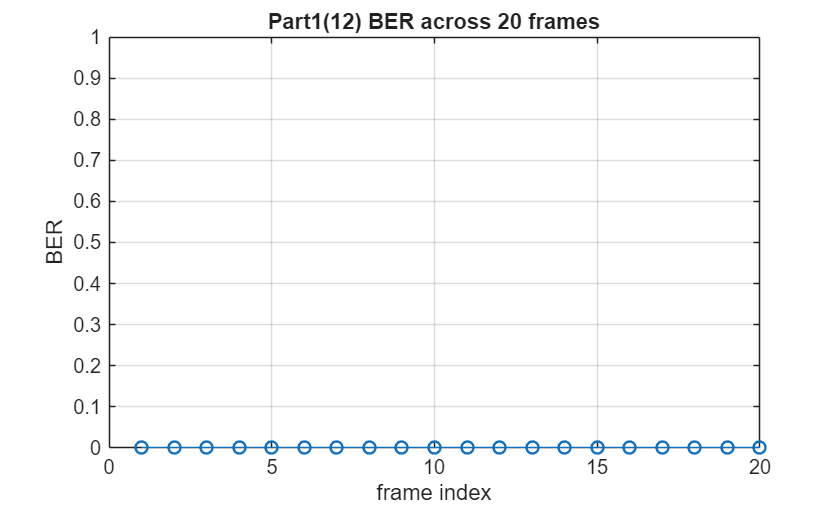

[BER_frame, ~, err_bits_sc, tot_bits_sc, ~] = run_16QAM(1e6, 1e-5);
frame_index = 1:1:20;
figure;
plot(frame_index, BER_frame(1,frame_index), 'o-', 'Linewidth', 1.2);
title('Part1(12) BER across 20 frames');
xlabel('frame index'); ylabel('BER'); grid on;
ylim([0 1]);

fprintf('Total BER = %f', mean(BER_frame));

Total BER = 0.000055

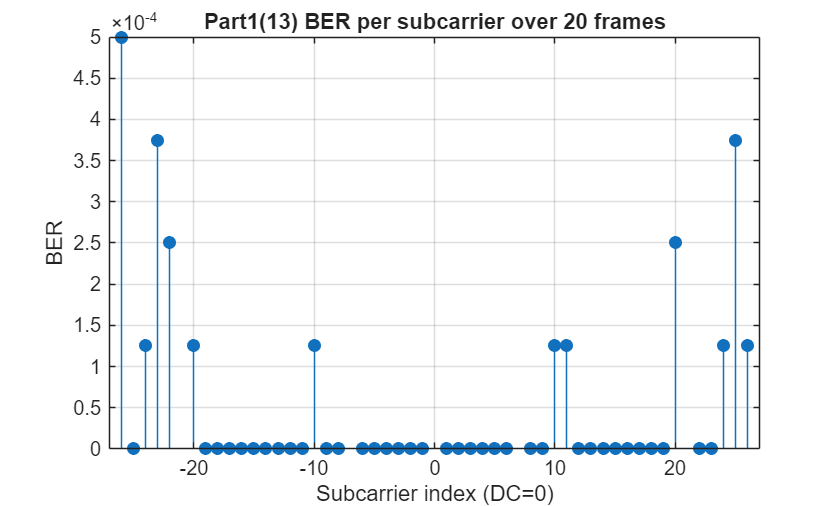

% Part1(13)
BER_sc = err_bits_sc ./ max(1, tot_bits_sc);  
figure;
stem(data_sc, BER_sc, 'filled'); grid on;
xlabel('Subcarrier index (DC=0)'); ylabel('BER');
title('Part1(13) BER per subcarrier over 20 frames');

Yes, from the figure we can clearly observe frequency-dependent BER behavior. In particular, the subcarriers near the band edges experience noticeably higher BER. We believe this is mainly due to two factors:

(1) the non-flat passband response of the USRP analog front-end filters, which causes additional attenuation and noise at high subcarrier frequencies; and

(2) Less accurate channel equalization near the band edges (from Part1(6) figure 1, we can observe that the channel magnitude is less at the subcarrier far from center, which implies possible lower SNR), where the estimated channel response is more sensitive to noise and interpolation errors.

% Part1(14)
dist_list = [0.5 1.0 1.5 2.0];
BER_dist = zeros(size(dist_list));

[~, BER_dist(1), ~, ~] = run_16QAM(1e6, 1e-5);
fprintf('d=0.5m, BER = %f', BER_dist(1));

d=0.5m, BER = 0.000010

[~, BER_dist(2), ~, ~, ~] = run_16QAM(1e6, 1e-6);
fprintf('d=1.0m, BER = %f', BER_dist(2));

d=1.0m, BER = 0.000216

[~, BER_dist(3), ~, ~, ~] = run_16QAM(1e6, 1e-6);
fprintf('d=1.5m, BER = %f', BER_dist(3));

d=1.5m, BER = 0.003719

[~, BER_dist(4), ~, ~, ~] = run_16QAM(1e6, 1e-6);
fprintf('d=2.0m, BER = %f', BER_dist(4));

d=2.0m, BER = 0.006318

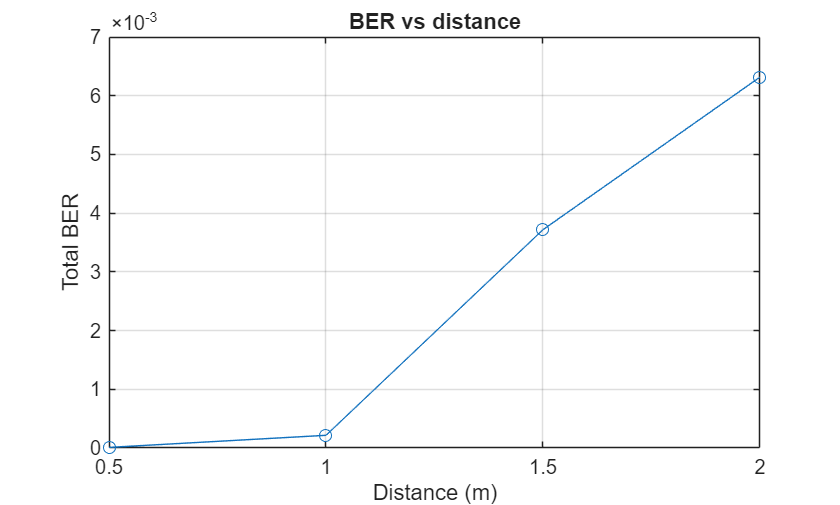

figure; plot(dist_list, BER_dist, 'o-'); grid on;
xlabel('Distance (m)'); ylabel('Total BER');
title('BER vs distance');

% Part1(15)

Follow this: $f_s=\frac{f_{master}}{\text{interpolation/decimation}}=10M$ to set our parameters.

The master clock rate of USRP 2920 is 100MHz, hence the interpolation factor of USRP 2920 is 100MHz/10MHz  = **10**.

The master clock rate of USRP 2901 is 20MHz (As 16 required), hence the decimation factor of USRP 2901  is 20MHz/10MHz  = **2**.

The maximal master clock rate of USRP 2920 is **100MHz** because it is fixed.

The maximal master clock rate of USRP 2901 is **61.44MHz**.

(See the below figure)

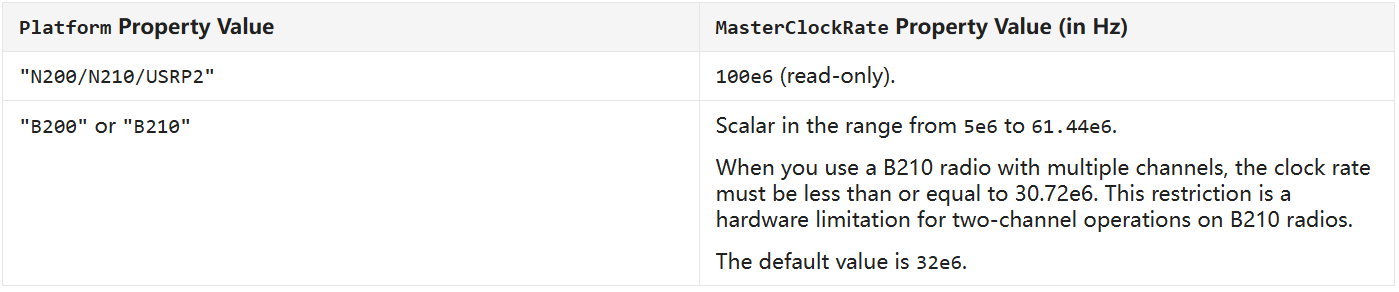

% Part1(16)
[BER_frame_1MHz, ~, ~, ~, total_time_1MHz] = run_16QAM(1e6, 1e-5);
[BER_frame_10MHz, ~, ~, ~, total_time_10MHz] = run_16QAM(10e6, 1e-5);
fprintf('Transmission time for 1MHz:%fs\nTransmission time for 10MHz:%fs', total_time_1MHz, total_time_10MHz);

Transmission time for 1MHz:4.777932s
Transmission time for 10MHz:0.577015s

Transmission time is computed by summing only the successful transmissions (i.e., frames that can be added to the buffer).

Therefore, the transmission time strongly depends on the sampling rate, and **the total time at 10 MHz is much shorter than at 1 MHz.**

However, if we consider the actual total processing time—including the frames that are discarded—the overall duration becomes similar for both sampling rates.(18s vs 15s)

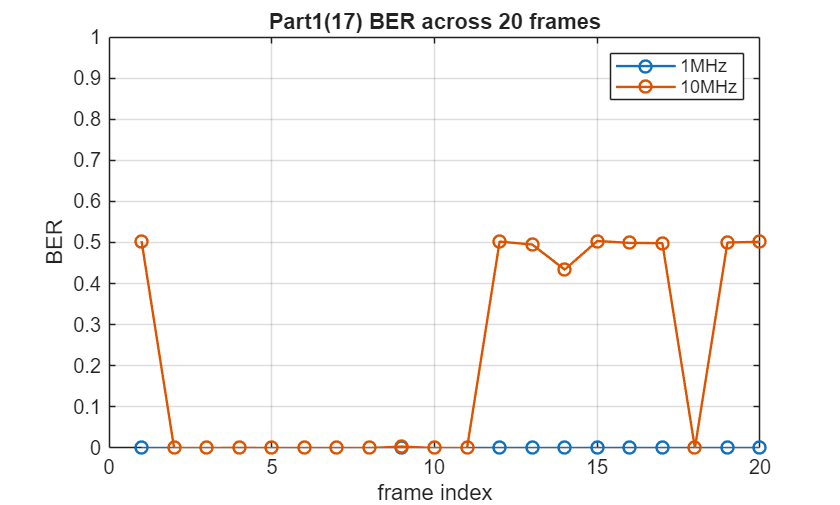

% Part1(17)
figure;
frame_index = 1:1:20;
plot(frame_index, BER_frame_1MHz(1,frame_index), 'o-', 'Linewidth', 1.2);
grid on;hold on;
plot(frame_index, BER_frame_10MHz(1,frame_index), 'o-', 'Linewidth', 1.2);
title('Part1(17) BER across 20 frames');
xlabel('frame index'); ylabel('BER'); 
legend('1MHz', '10MHz');
ylim([0 1]);

We find that our transmission framework is robust for sampling rate = 1MHz, as all BER in 20 frames are all closed to 0.

However, some of the BER for sampling rate = 10MHz are closed to 0.5, so our method fails sometimes to synchronize and thus fails to correctly decode the data.